# A few examples on how to use the Simscape battery library models through code

**WMG, University of Warwick**

W.D. Widanage 19/09/2021 - 18/06/2023  (Turn the page)

## Introduction

This live editior script includes five examples, based on the TSPMe model and the TSPMeA  (simiar methods can be develeoped for the TECM and TECMD models from the library as well)

- A 1C current discharge with TSPMe

- A power profile based discharge with TSPMe 

- Simulating a series of events in succession with TSPMe

- Estimating Remaining-Useful-Energy and Time-to-Discharge with TSPMe

- Perform CCCV-CC cycle ageing at 25degC with TSPMeA

Tip: Run one section at a time rather than running the entire file.

## Eg. 1: A 1C discharge - the "Hello World" of a battery model

Simulate a standard 1C discharge from 100% SoC until Vmin

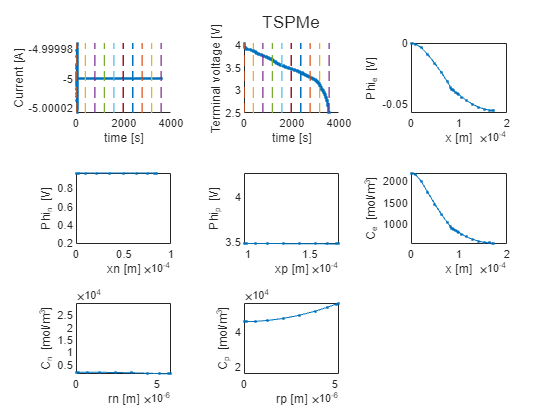

clear, clc
import BatteryLibrary.Utilities.*
simuLinkMdlStr = 'TSPMe_Prototype';                                                     % Specify the simulink file name (without the file extension)
load_system(simuLinkMdlStr+".slx")
set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','off');
Vmax = 4.2;                                                                             % Set upper cut-off voltage [V]
Vmin = 2.5;                                                                             % Set lower cut-off voltage for terminating discharge [V]

modelProp = Simulink.SimulationInput(simuLinkMdlStr);                                   % Create an instance of a Matlab SimulationInput class to simulate

% CC Discharge
appCurr = -5*timeseries(1,0,'Name',"I");                                                % Generate 1C input current as a timeseries object (1C := 5A) [A]
modelProp = modelProp.setExternalInput('appCurr');                                      % Set the external input to the model
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/TSPMe'],'z0',num2str(1));     % Set initial cell SoC to 100%
modelProp = modelProp.setModelParameter('StopTime','inf','SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint'); % Set simuation options
simOut_D = sim(modelProp);                                                              % Simulate the "modelProp" object with above specifications

% Once simulation is complete plot the summary results, note "TSPMe" is the
% name of the corresponding model component in TSPMe_Prototype.slx;
plotVariables(simOut_D,"TSPMe")

save_system(simuLinkMdlStr+".slx")
close_system(simuLinkMdlStr+".slx")

## Eg. 2: Applying a power profile as input

Apply a constant power discharge with a cell initial soc of 70%, intial cell temperature of 10degC and ambient temperature of 25degC 

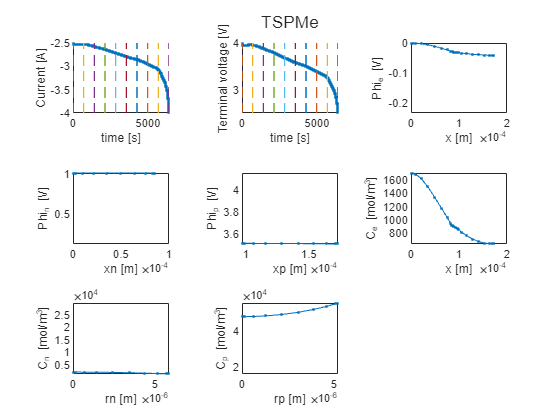

clear, clc
import BatteryLibrary.Utilities.*
simuLinkMdlStr = 'TSPMe_Prototype';                                                                             % Specify the simulink file name (without the file extension)
load_system(simuLinkMdlStr+".slx")
set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','off');
Vmax = 4.2;                                                                                                     % Set upper cut-off voltage [V]
Vmin = 2.5;                                                                                                     % Set lower cut-off voltage for terminating discharge [V]

modelProp = Simulink.SimulationInput(simuLinkMdlStr);                                                           % Create an instance of a Matlab SimulationInput class to simulate


% Constant power discharge
appPow = -10*timeseries(1,0,'Name',"P");                                                                        % Generate an input power profile as a timeseries object [W]
modelProp = modelProp.setExternalInput('appPow');                                                               % Set an external input to the model
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','2');                   % Set the "Electrical Source" block to "2" for a power input. Options: "0": Current, "1": Voltage, "2": Power

% Changing any intial conditions if needed:
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/TSPMe'],'z0',num2str(1));                           % Initial cell SoC, let's assume 70%
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Temperature Source'],'temperature',num2str(298));     % Ambient temperature [K], let's assume room temperature
modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/TSPMe'],'T0',num2str(283));                           % Initial cell temperature [K], let's assume 283K (10degC)

modelProp = modelProp.setModelParameter('StopTime','inf','SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint'); % Set simuation options

simOut_P = sim(modelProp);                                                                                      % Simulate the "modelProp" object with the above specifications

% Once simulation is complete plot the summary results, note "TSPMe" is the
% name of the corresponding model component in TSPMe_Prototype.slx;
plotVariables(simOut_P,"TSPMe")

save_system(simuLinkMdlStr+".slx")
close_system(simuLinkMdlStr+".slx")

## Eg. 3: Simulate a series of events: CP -> Rest -> CCCV

This is an example that performs a series of events while changing the input from a power profile, to a rest and then to a current profile. The series of events are:

- constant **power** discharge, 

- followed by a **rest period** 

- and then a **CCCV charge** as the input. 

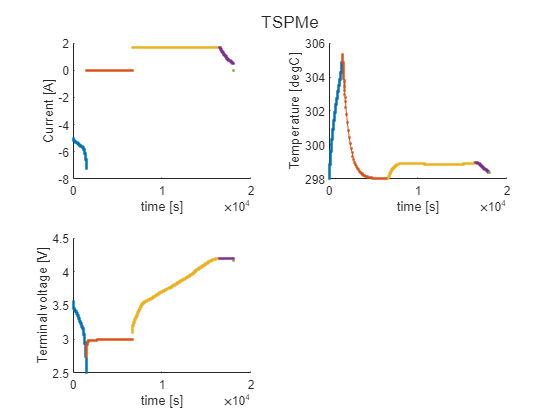

clear, clc
import BatteryLibrary.Utilities.*
simuLinkMdlStr = 'TSPMe_Prototype';                         % Specify the simulink file name (without the file extension)
load_system(simuLinkMdlStr+".slx")

modelProp = Simulink.SimulationInput(simuLinkMdlStr);       % Create an instance of a Matlab SimulationInput class to simulate
set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','off');

Vmax = 4.2;                                                 % Set upper cut-off voltage to terminate CC charge [V]
Vmin = 2.5;                                                 % Set lower cut-off voltage to terminate CP discharge [V]

evtList = ["CP_D","Rest","CC_C","CV","Rest"];               % Define the sequence of events

for ee = 1:length(evtList)
    if ee > 1
        op = simscape.op.create(simOut_E(ee-1).simlog, simOut_E(ee-1).tout(end));
        set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','on');
        set_param(simuLinkMdlStr,'SimscapeOperatingPoint','op');
    end
    if evtList(ee) == "CP_D"
        appCurr = -18*timeseries(1,0,'Name',"I");           % CP discharge [W] 
        modelProp = modelProp.setExternalInput('appCurr');  % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','2');   % Set the "Electrical Source" block to '0' for a current input. Options: '0': Current, '1': Voltage, '2': Power
        tEnd = 'inf';                                       % Set simulation time to 'inf'
    elseif evtList(ee) == "Rest"
        tRest = 3600;                                       % Rest time [s]
        appCurr = 0*timeseries(1,0,'Name',"I");             % Set input current to 0A [A]
        modelProp = modelProp.setExternalInput('appCurr');  % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','0');   % Set the "Electrical Source" block to '0' for a current input. Options: '0': Current, '1': Voltage, '2': Power
        tEnd = num2str(simOut_E(ee-1).OperPoint.snapshotTime + tRest); % Update the simualtion end time from previous event endtime

    elseif evtList(ee) == "CC_C"
        appCurr = 5/3*timeseries(1,0,'Name',"I");            % C/3 charge [A] (1C := 5A)
        modelProp = modelProp.setExternalInput('appCurr');   % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','0');   % Set the "Electrical Source" block to '0' for a current input. Options: '0': Current, '1': Voltage, '2': Power
        tEnd = 'inf';                                        % Set simulation time to 'inf'
    elseif evtList(ee) == "CV"
        appVol = Vmax*timeseries(1,0,'Name',"V");            % Constant voltage [V]
        modelProp = modelProp.setExternalInput('appVol');    % Set an external input to the model
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','1');                   % Set the "Electrical Source" block to '1' for a voltage input. Options: '0': Current, '1': Voltage, '2': Power
        modelProp = modelProp.setBlockParameter([simuLinkMdlStr,'/Terminate CV mode/enableCV'],'value',num2str(1));     % Enable CV mode 
        tEnd = 'inf';                                        % Set simulation time to 'inf'
    end

 
    modelProp = modelProp.setModelParameter('StopTime',tEnd,'SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint');
    simOut_E(ee,1) = sim(modelProp);
end

% Once simulation is complete plot the summary results, note "TSPMe" is the
% name of the corresponding model component in TSPMe_Prototype.slx;
plotVariables(simOut_E,"TSPMe", number_of_snapshots=10, plot=["I","V","T"])


% % Once simulation is complete plot the key variables I/V/T, SoC, electrode potentials at
% % the current collector and OCV
save_system(simuLinkMdlStr+".slx")
close_system(simuLinkMdlStr+".slx")


## Eg. 4: Compute Remaning Useful Energy and Time-To-Discharge maps with TSPMe

Use the TSPMe model to calculate the Remaining Useful Energy (RUE) and Time to Discharge (TTD) of the cell as a function of different starting SoCs, starting temperatures and discharge powers

clear, clc
simuLinkMdlStr = 'TSPMe_Prototype';             % Specify the simulink file name (without the file extension)
load_system(simuLinkMdlStr+".slx")
set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','off');
save_system(simuLinkMdlStr+".slx")

nomE = 17.5;                                    % Nominal cell (LG M50) energy [Wh] @ 25degC
Vmax = 4.2;                                     % Set upper cut-off voltage
Vmin = 2.5;                                     % Set lower cut-off voltage for RUE/TTD

lowestSoC = 0.1;                                % Lowest starting SoC for RUE
highestSoC = 1;                                 % Highest starting SoC for RUE
nZ = 6;                                         % Number of SoC points
z0 = linspace(lowestSoC,highestSoC,nZ);         % Initial cell SoCs for RUE [-]

lowestPow = -2;                                 % Lowest discharge power, negative for discharge [W]
highestPow = -25;                               % Highest discharge power, negative for discharge [W]
nP = 6;                                         % Number of different input discarge power rates
P = linspace(lowestPow,highestPow,nP);          % Discharge powers [W]

lowestAmbTemp = 10;                             % Lowest starting ambient temperature [degC]
highestAmbTemp = 40;                            % Highest starting ambient temperature [degC]
nT = 4;                                         % Number of temperautre points
ambTemp = linspace(lowestAmbTemp,highestAmbTemp,nT) + 273;   % Ambient temperatures for RUE [K]

%% Parameters: Thermal
T0 = ambTemp;                                   % Initial cell temperature [K] -  In these simulations the initial cell temperature is identical to the ambient temperautre set


% A unit amplitude power timeseries object
powVec = timeseries(1,0,'Name',"P");

cntr = 0;
for jj = 1:nT                                   % Loop over the temperatures
    for ii = 1:nP                               % Loop over the input applied powers
        for zz = 1:nZ                           % Loop over the initial SoCs
            cntr = cntr + 1;

            %% Create a model SimulationInput object
            modelProp(cntr) = Simulink.SimulationInput(simuLinkMdlStr);

            % Set input
            ps = powVec*P(ii); ps.Name = "power";
            modelProp(cntr) = modelProp(cntr).setExternalInput('ps');
            modelProp(cntr) = modelProp(cntr).setVariable('ps',ps,'Workspace',simuLinkMdlStr);
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/Electrical Source'], 'inType','2');   % Set the "Electrical Source" block to '2' for a power input. Options: '0': Current, '1': Voltage, '2': Power


            % Set TSPMe initial conditions, of cell and ambient temperature and cell SoC
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/Temperature Source'],'temperature',num2str(ambTemp(jj)));
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/TSPMe'],'T0',num2str(T0(jj)));
            modelProp(cntr) = modelProp(cntr).setBlockParameter([simuLinkMdlStr,'/TSPMe'],'z0',num2str(z0(zz)));

            % Simulation run time settings
            modelProp(cntr) = modelProp(cntr).setModelParameter('StopTime','10E5','SaveState','on','SaveOutput','on','SaveOperatingPoint','on', ...
                                                                'SaveFinalState','on','FinalStateName','OperPoint');
        end
    end
end

%% Simulate in parallel using parsim
tic
simOut = parsim(modelProp,'TransferBaseWorkspaceVariables',"on","ShowProgress","on");

[11-Aug-2023 13:15:56] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
[11-Aug-2023 13:17:57] Starting Simulink on parallel workers...
[11-Aug-2023 13:18:08] Configuring simulation cache folder on parallel workers...
[11-Aug-2023 13:18:08] Transferring base workspace variables used in the model to parallel workers...
[11-Aug-2023 13:18:09] Loading model on parallel workers...
[11-Aug-2023 13:18:26] Running simulations...
[11-Aug-2023 13:18:44] Completed 1 of 144 simulation runs
[11-Aug-2023 13:18:44] Completed 2 of 144 simulation runs
[11-Aug-2023 13:18:44] Completed 3 of 144 simulation runs
[11-Aug-2023 13:18:44] Completed 4 of 144 simulation runs
[11-Aug-2023 13:18:44] Completed 5 of 144 simulation runs
[11-Aug-2023 13:18:44] Completed 6 of 144 simulation runs
[11-Aug-2023 13:18:47] Completed 7 of 144 simulation runs
[11-Aug-2023 13:18:47] Completed 8 of 144 simulation runs
[11

toc

Elapsed time is 228.441483 seconds.


#### Calculate Time-to-Discharge (TTD) and Remaining Useful Energy (RUE)

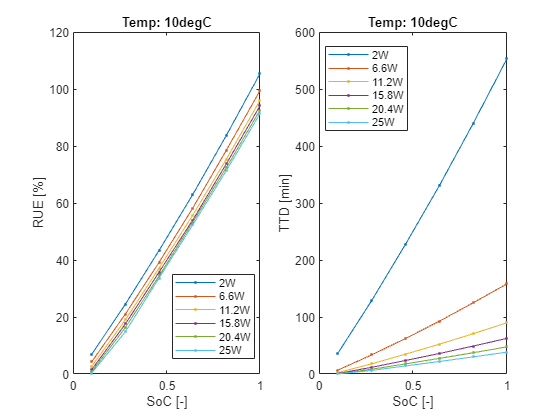

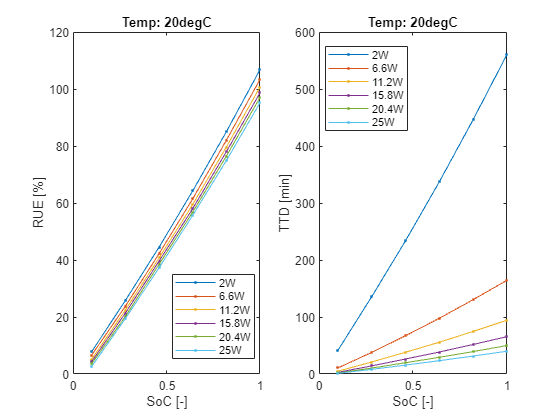

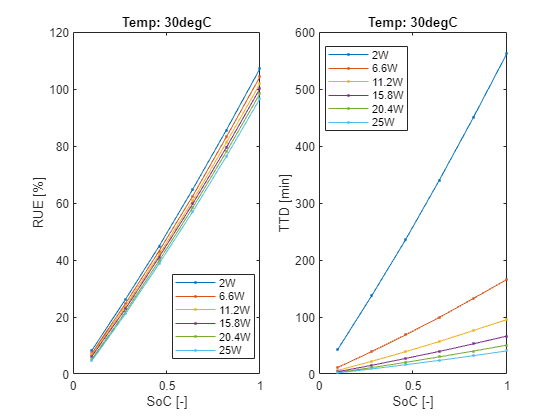

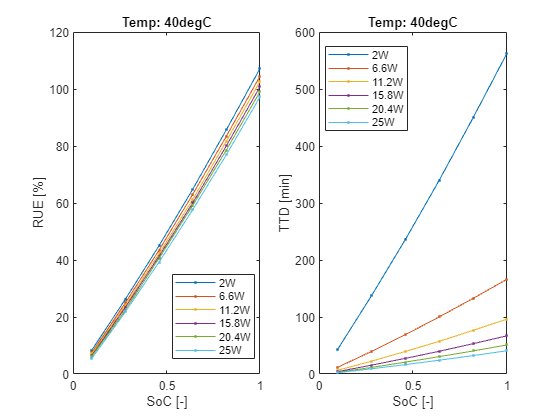

for ii = 1:cntr
    mdlCurr = find(simOut(ii).logsout,'I');
    mdlVol = find(simOut(ii).logsout,'V');
    appP = min(mdlCurr.Values.*mdlVol.Values);
    TTDVec(ii,1) = max(mdlCurr.Values.Time)/60;     % Time to discharge in minutes
    RUEVec(ii,1) = -appP *TTDVec(ii)/60;            % RUE in [Wh] - Integration simplifies to a multiplcation because the discharge power is a constant
end

% Reshape TTD and RUE into nZ x nP x nT
TTD = reshape(TTDVec,nZ,nP,nT);
RUE = reshape(RUEVec,nZ,nP,nT)/nomE*100;            % Relative RUE

% Plot TTD and RUE vs SoC for each ambient temperature
for tt = 1:nT
    figure
    subplot(1,2,1)
    plot(z0,RUE(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('SoC [-]'); ylabel('RUE [%]'); legend(string(-P)+"W",'Location',"best")
    subplot(1,2,2)
    plot(z0,TTD(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('SoC [-]'); ylabel('TTD [min]'); legend(string(-P)+"W",'Location',"best")
end

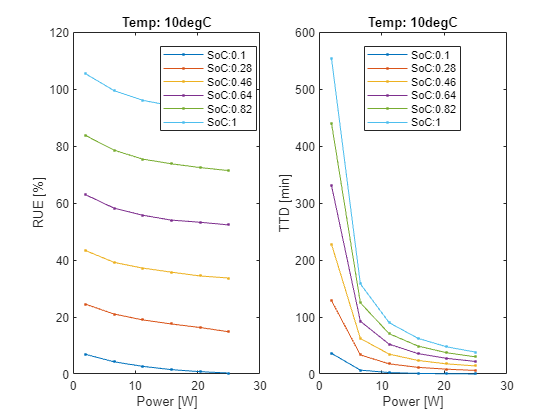

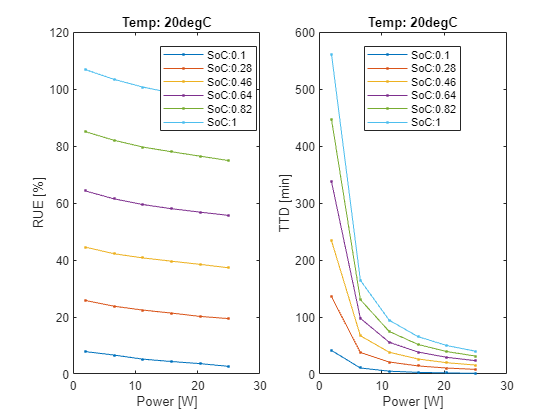

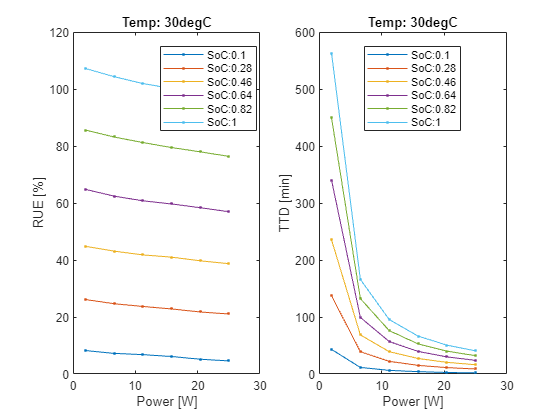

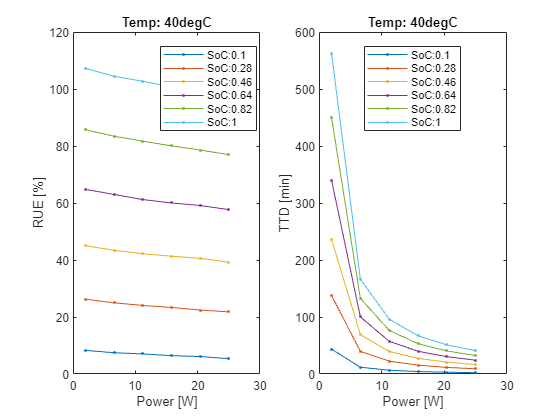


% Plot TTD and RUE vs discharge power for each ambient temperature
RUE_P = permute(RUE,[2,1,3]);        % nP, nZ, nT
TTD_P = permute(TTD,[2,1,3]);        % nP, nZ, nT
for tt = 1:nT
    figure
    subplot(1,2,1)
    plot(-P,RUE_P(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('Power [W]'); ylabel('RUE [%]'); legend(["SoC:" + string(z0)],'Location',"best")
    subplot(1,2,2)
    plot(-P,TTD_P(:,:,tt),'. -'); title("Temp: "+string(ambTemp(tt)-273)+"degC")
    xlabel('Power [W]'); ylabel('TTD [min]'); legend(["SoC:" + string(z0)],'Location',"best")
end


save_system(simuLinkMdlStr+".slx")
close_system(simuLinkMdlStr+".slx")

## Eg. 5: Perform a cycling ageing simulation

This example performs a cycling ageing simulation at a set ambient temperature, CCCV charge and CC-discharge.

clear, clc
import BatteryLibrary.Utilities.*
simuLinkMdlStr = 'TSPMeA_Cycling';                           % Specify the cycle ageing simulink file name (without the file extension)
load_system(simuLinkMdlStr+".slx")

modelCycle = Simulink.SimulationInput(simuLinkMdlStr);       % Create an instance of a Matlab SimulationInput class to simulate
set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','off');

% Cycle ageing conditions
Vmax = 4.2;                        % Set upper cut-off voltage to terminate CC charge [V]
Vmin = 2.5;                        % Set lower cut-off voltage to terminate CP discharge [V]
Ic = 5/3;                          % Cycling charge current [A]
Id = -5;                           % Cycling discharge current [A]
ambTemp = 298;                     % Cycling ambient temperatuer [K]
number_of_RPTs = 10;               % Number of snapshots for capacity fade
number_of_cycles = 100;            % Number of cycles per RPT

% Set cycler settings in Simulink model
modelCycle = modelCycle.setBlockParameter([simuLinkMdlStr,'/Simple cycler'], 'Vmax',num2str(Vmax));   % Set Vmax
modelCycle = modelCycle.setBlockParameter([simuLinkMdlStr,'/Simple cycler'], 'Vmin',num2str(Vmin));   % Set Vmin 
modelCycle = modelCycle.setBlockParameter([simuLinkMdlStr,'/Simple cycler'], 'Ic',num2str(Ic));       % Set charge current 
modelCycle = modelCycle.setBlockParameter([simuLinkMdlStr,'/Simple cycler'], 'Id',num2str(Id));       % Set discharge current 
modelCycle = modelCycle.setBlockParameter([simuLinkMdlStr,'/Temperature Source'],'temperature',num2str(ambTemp)); % Set ambient temperature
modelCycle = modelCycle.setBlockParameter([simuLinkMdlStr,'/TSPMeA'],'T0',num2str(ambTemp));                      % Set cell temperature

% Initialise SoH at RPT0
SoH = nan(number_of_RPTs,1);
SoH(1,1) = 1;

tic
for rr = 1:number_of_RPTs
    modelCycle = modelCycle.setModelParameter('StopTime','50E6','SaveState','on','SaveOutput','on','SaveFinalState','on','FinalStateName','OperPoint');
    simOut_cycle = sim(modelCycle);

    % Get SoH
    signals_cycling = getVariables(simOut_cycle,"TSPMeA");
    if rr > 1
        SoH(rr,1) = signals_cycling.TSPMeA.SR.SoH(end);         % SoH [-]
    end

    op = simscape.op.create(simOut_cycle.simlog, simOut_cycle.tout(end));
    set_param(simuLinkMdlStr,'SimscapeUseOperatingPoints','on'); 
    set_param(simuLinkMdlStr,'SimscapeOperatingPoint','op'); 

end
toc

Elapsed time is 364.844338 seconds.


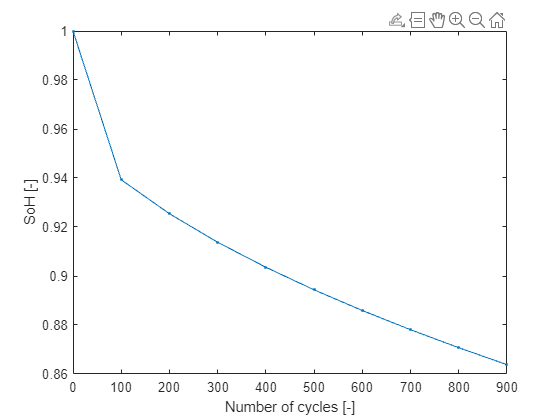

% Plot cycle ageing capacity
figure
plot((0:number_of_RPTs-1)*number_of_cycles',SoH,'.-')
xlabel("Number of cycles [-]"); ylabel("SoH [-]"); 

save_system(simuLinkMdlStr +".slx"); close_system(simuLinkMdlStr +".slx")
